# MECH468 Homework 5

## Setup

First, let's load the system parameters:

clear all
format shortG
format compact
%% Motor
% Resistance
Rm = 8.4;
% Current-torque (N-m/A)
kt = 0.042;
% Back-emf constant (V-s/rad)
km = 0.042;

%% Rotary Arm
% Mass (kg)
mr = 0.095;
% Total length (m)
r = 0.085;
% Moment of inertia about pivot (kg-m^2)
Jr = mr*r^2/3;
% Equivalent Viscous Damping Coefficient (N-m-s/rad)
br = 1e-3; % damping tuned heuristically to match QUBE-Sero 2 response

%% Pendulum Link
% Mass (kg)
mp = 0.024;
% Total length (m)
Lp = 0.129;
% Pendulum center of mass (m)
l = Lp/2;
% Moment of inertia about pivot (kg-m^2)
Jp = mp*Lp^2/3;
% Equivalent Viscous Damping Coefficient (N-m-s/rad)
bp = 5e-5; % damping tuned heuristically to match QUBE-Sero 2 response
% Gravity Constant
g = 9.81;

Next, creating our state space matricies:

% Find Total Inertia
Jt = Jr*Jp - mp^2*r^2*l^2;
% 
% State Space Representation
A = [0 0 1 0;
     0 0 0 1;
     0 mp^2*l^2*r*g/Jt  -br*Jp/Jt   -mp*l*r*bp/Jt 
     0  mp*g*l*Jr/Jt    -mp*l*r*br/Jt   -Jr*bp/Jt];

B = [0; 0; Jp/Jt; mp*l*r/Jt];
C = eye(2,4);
D = zeros(2,1);


% Add actuator dynamics
B = km * B / Rm;
A(3,3) = A(3,3) - km*km/Rm*B(3);
A(4,3) = A(4,3) - km*km/Rm*B(4);

Defining our discrete time system:

% Discretization with sampling time T = 0.002 sec
T = 0.002;
sys = ss(A,B,C,D);
sysd = c2d(sys,T);

## LQR Controller Design

### Verification with Simulation

Let's start with identity matrices for $Q$ and $R$ and do our pole placement.

Q = eye(4);
R = eye(1);
K = lqr(sysd, Q, R)

K =      -0.92188       32.862      -1.3509       2.8813


Let's check the system performance using our existing model (we assume that within $\pm 10^\circ$ the model accurately represents the real QUBE-Servo 2 system).

Creating our full state feedback state space model:

% Output full state for feedback simulation
C_full = eye(4);
D_full = zeros(4, 1);
% Start with zero velocity and motor angle, with pendulum at model limits
% as a worst case
icd = [0, deg2rad(-10), 0, 0];
sys_full = ss(A, B, C_full, D_full);
sysd_full = c2d(sys_full, T);

Loading it into a Simulink model (note: here we could have just used `feedback()` to construct the model and `initial()` to test it, however this would prevent us from being able to access the control input to the system $u$).

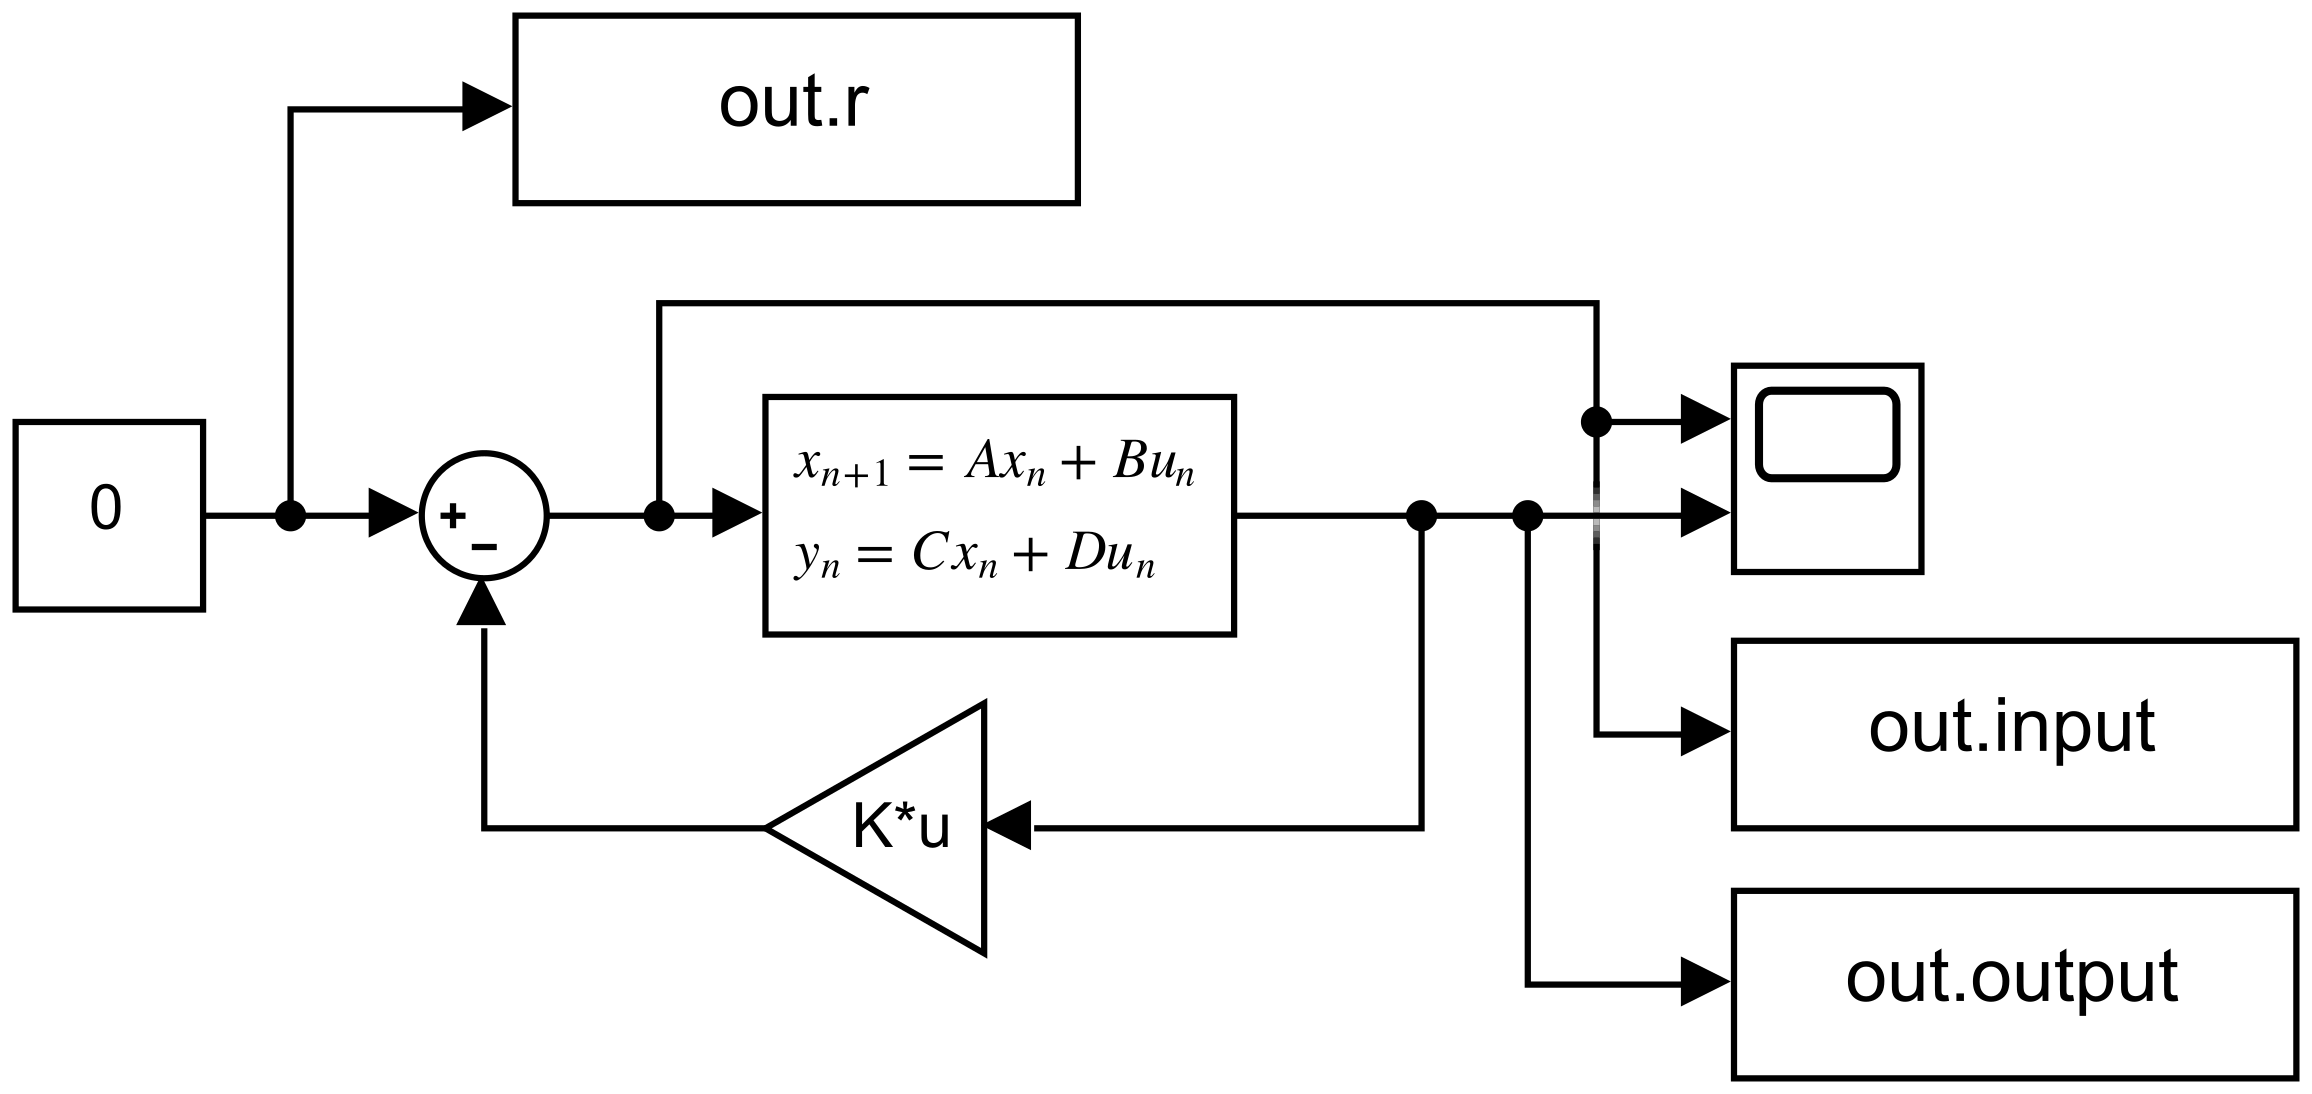

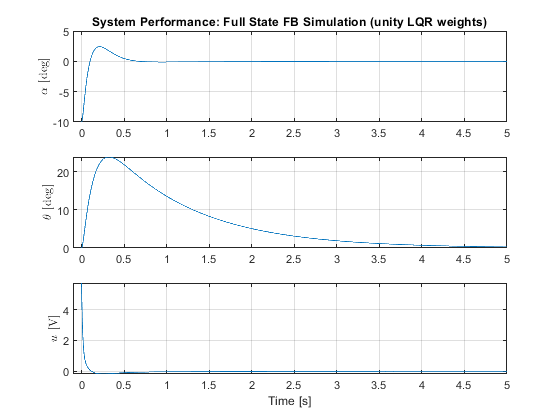

[t, u, r, theta, alpha] = fs_fb_sim();
plot_performance( ...
    t, u, r, theta, alpha, 'Full State FB Simulation (unity LQR weights)', 5)

This is a good start, we see that the pendulum quickly approaches the upright position. There is some overshoot, but importantly the overshoot does not exceed the bounds of our model. However, it looks like the motor location takes quite a while to converge, and there is also a rather high actuation command required. Since we already have pretty good performance in $\alpha$, let's see if we can trade some of it for better performance in $\theta$ and $u$.

R(1) = 100;
Q(1, 1) = 1000;
K = lqr(sysd, Q, R)

K =       -3.0461       24.809      -1.2376       1.9857


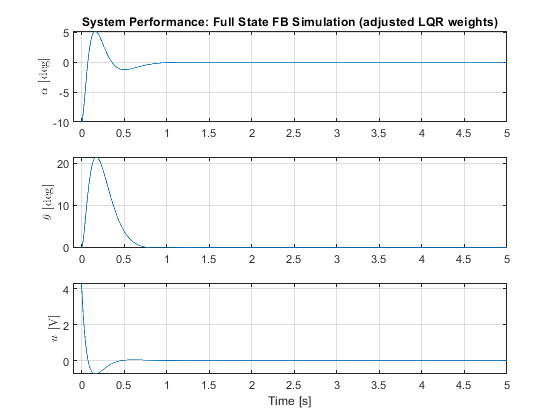

[t, u, r, theta, alpha] = fs_fb_sim();
plot_performance( ...
    t, u, r, theta, alpha, 'Full State FB Simulation (adjusted LQR weights)', 5);

### Testing with Real System

Testing it on the real system:

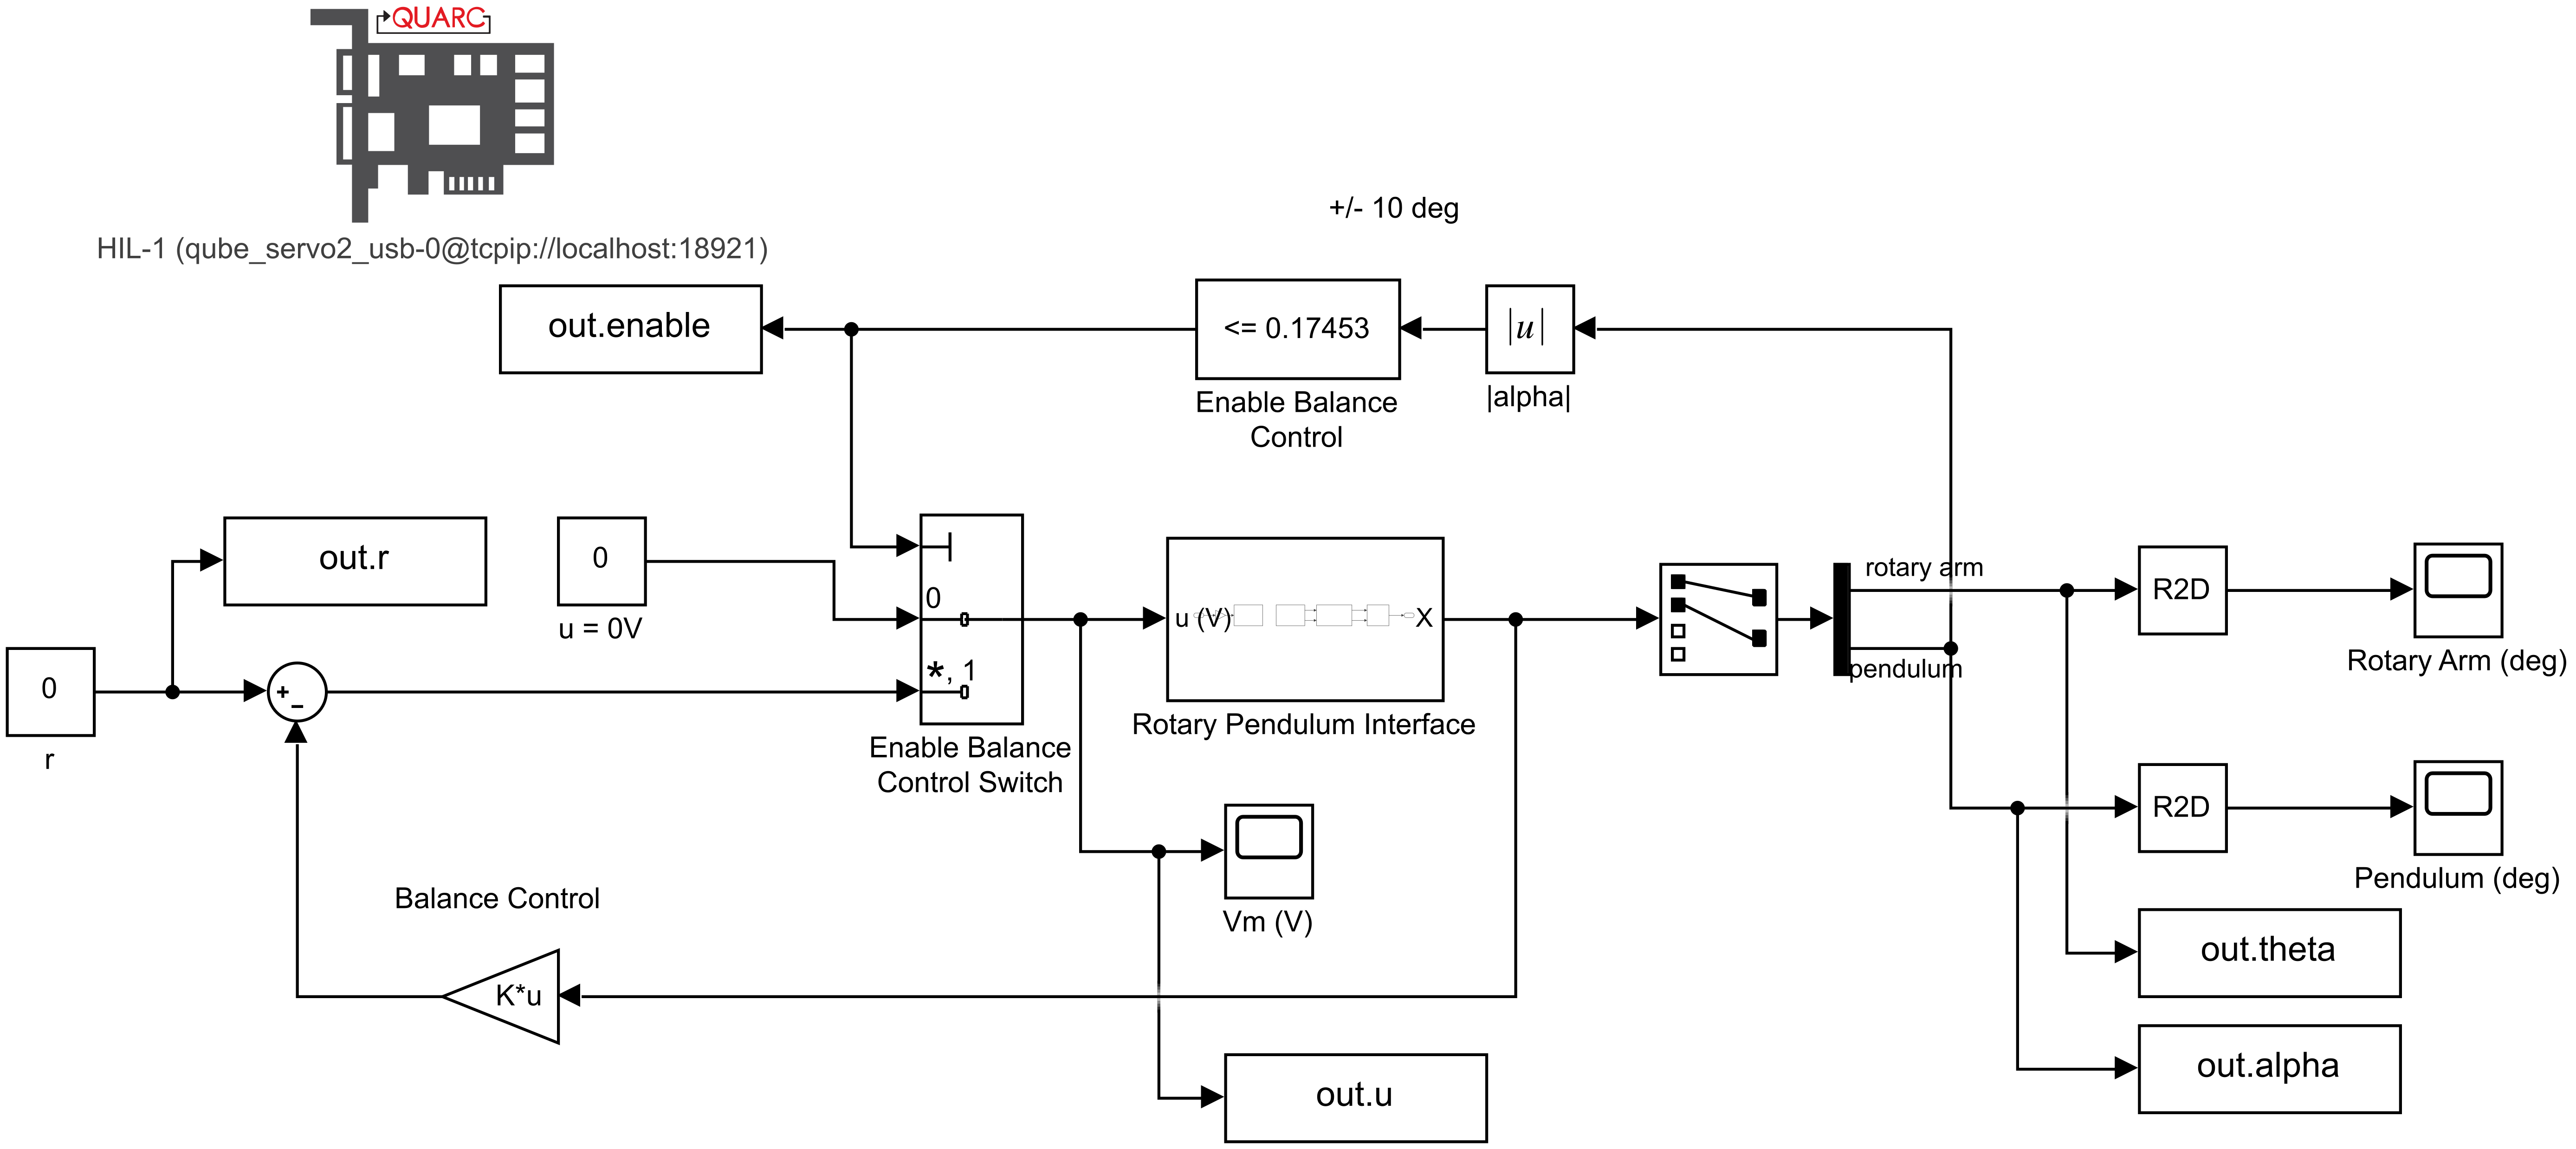

% Press lift pendulum while this is running (LED is green)
[t, u, r, theta, alpha] = run_sf();

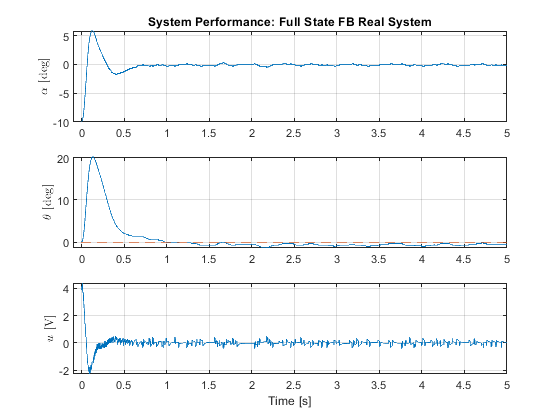

plot_performance( ...
    t, u, r, theta, alpha, 'Full State FB Real System', 5);

We see that the performance closely matches the model (not sure where the noise is coming from, perhaps the virtual QUBE-SERVO 2 models it internally, or this is a result of discretization or communication delay from the controller to the motor).

### LQR Weight Matrices

Let's print the matrices:

Q

Q =         1000           0           0           0
           0           1           0           0
           0           0           1           0
           0           0           0           1


R

R =    100

## Servo Controller Design

### Verification With Simulation

By augmenting our matrices, we can directly use pole placement (and hence LQR) to find our controller gains $K$ and $K_a$

Aaug = [sysd.A zeros(size(sysd.A,1),1);
    -sysd.C(1,:) 1];
Baug = [sysd.B; 0];
sysdaug = ss(Aaug,Baug,[sysd.C, [0; 0]], sysd.D,T);

% Reuse existing weight matrix
Qaug = Q;
% Increase Qaug size to match Aaug
Qaug(5, 5) = 1;
Kaug = lqr(sysdaug, Qaug, R);
K = Kaug(1:end - 1);
Ka = Kaug(end);

Checking our performance on a simulation:

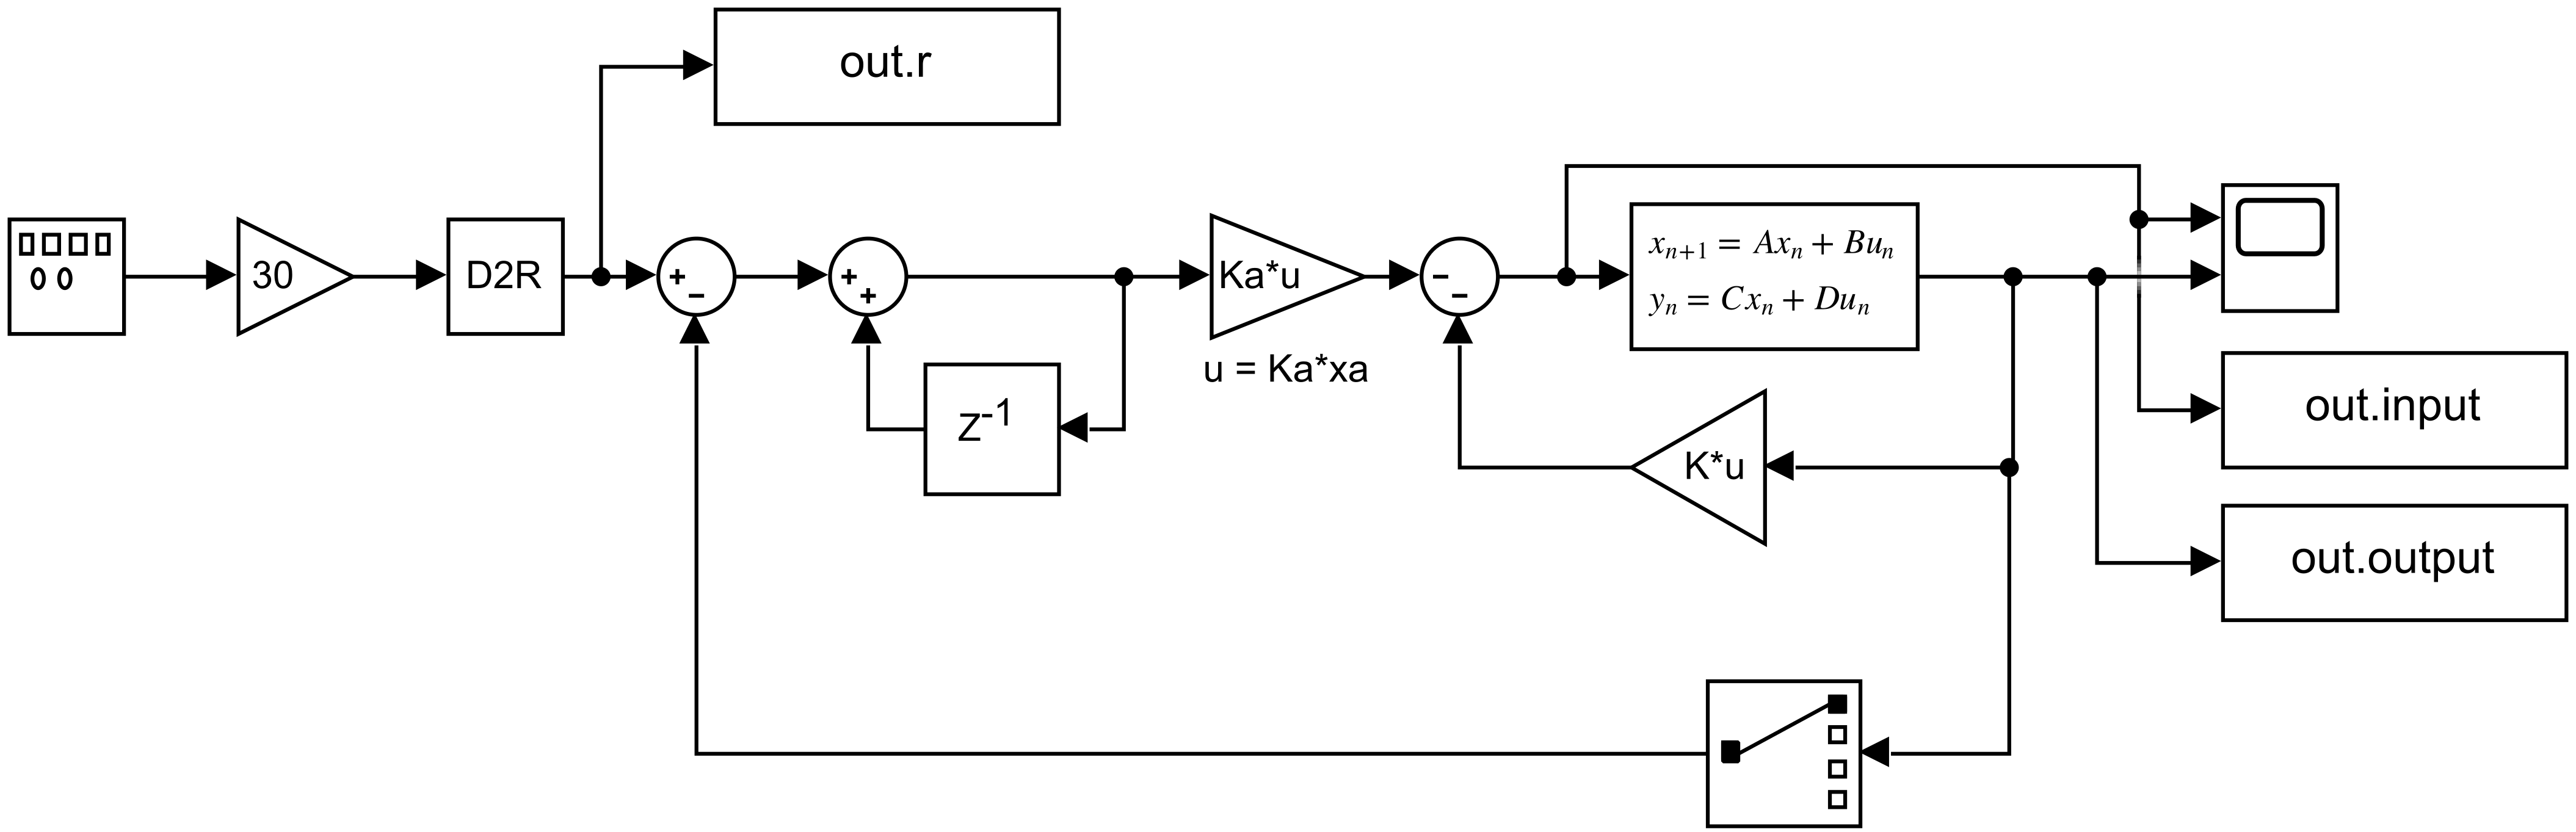

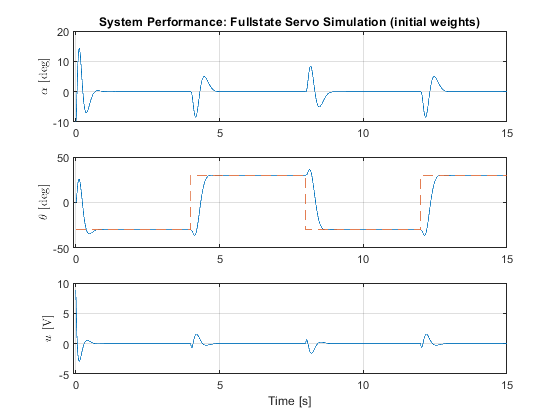

[t, u, r, theta, alpha] = fs_servo_sim();
plot_performance( ...
    t, u, r, theta, alpha, 'Fullstate Servo Simulation (initial weights)', 15);

We can see that the system does track the reference.

However, with the addition of the integrator term the pendulum now deviates from the limits of our model, and there is significant overshoot when the system needs to move to track the reference. Let's decrease the integrator weight to smooth these out.

Qaug(5, 5) = 0.03;
Kaug = lqr(sysdaug, Qaug, R);
K = Kaug(1:end - 1)

K =       -5.8183        30.08      -1.6735       2.4733


Ka = Kaug(end)

Ka =      0.016644

Checking our performance again:

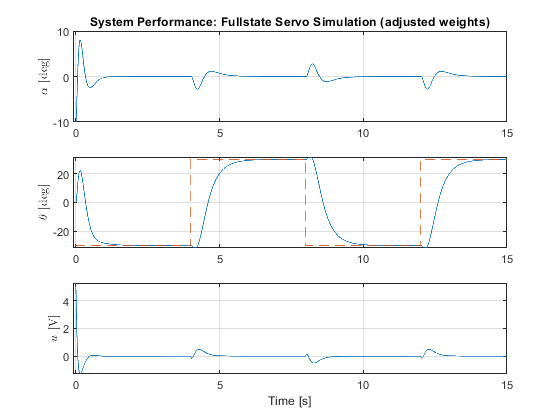

[t, u, r, theta, alpha] = fs_servo_sim();
plot_performance( ...
    t, u, r, theta, alpha, 'Fullstate Servo Simulation (adjusted weights)', 15);

### Testing with Real System

The tracking looks good, let's test it on the real system:

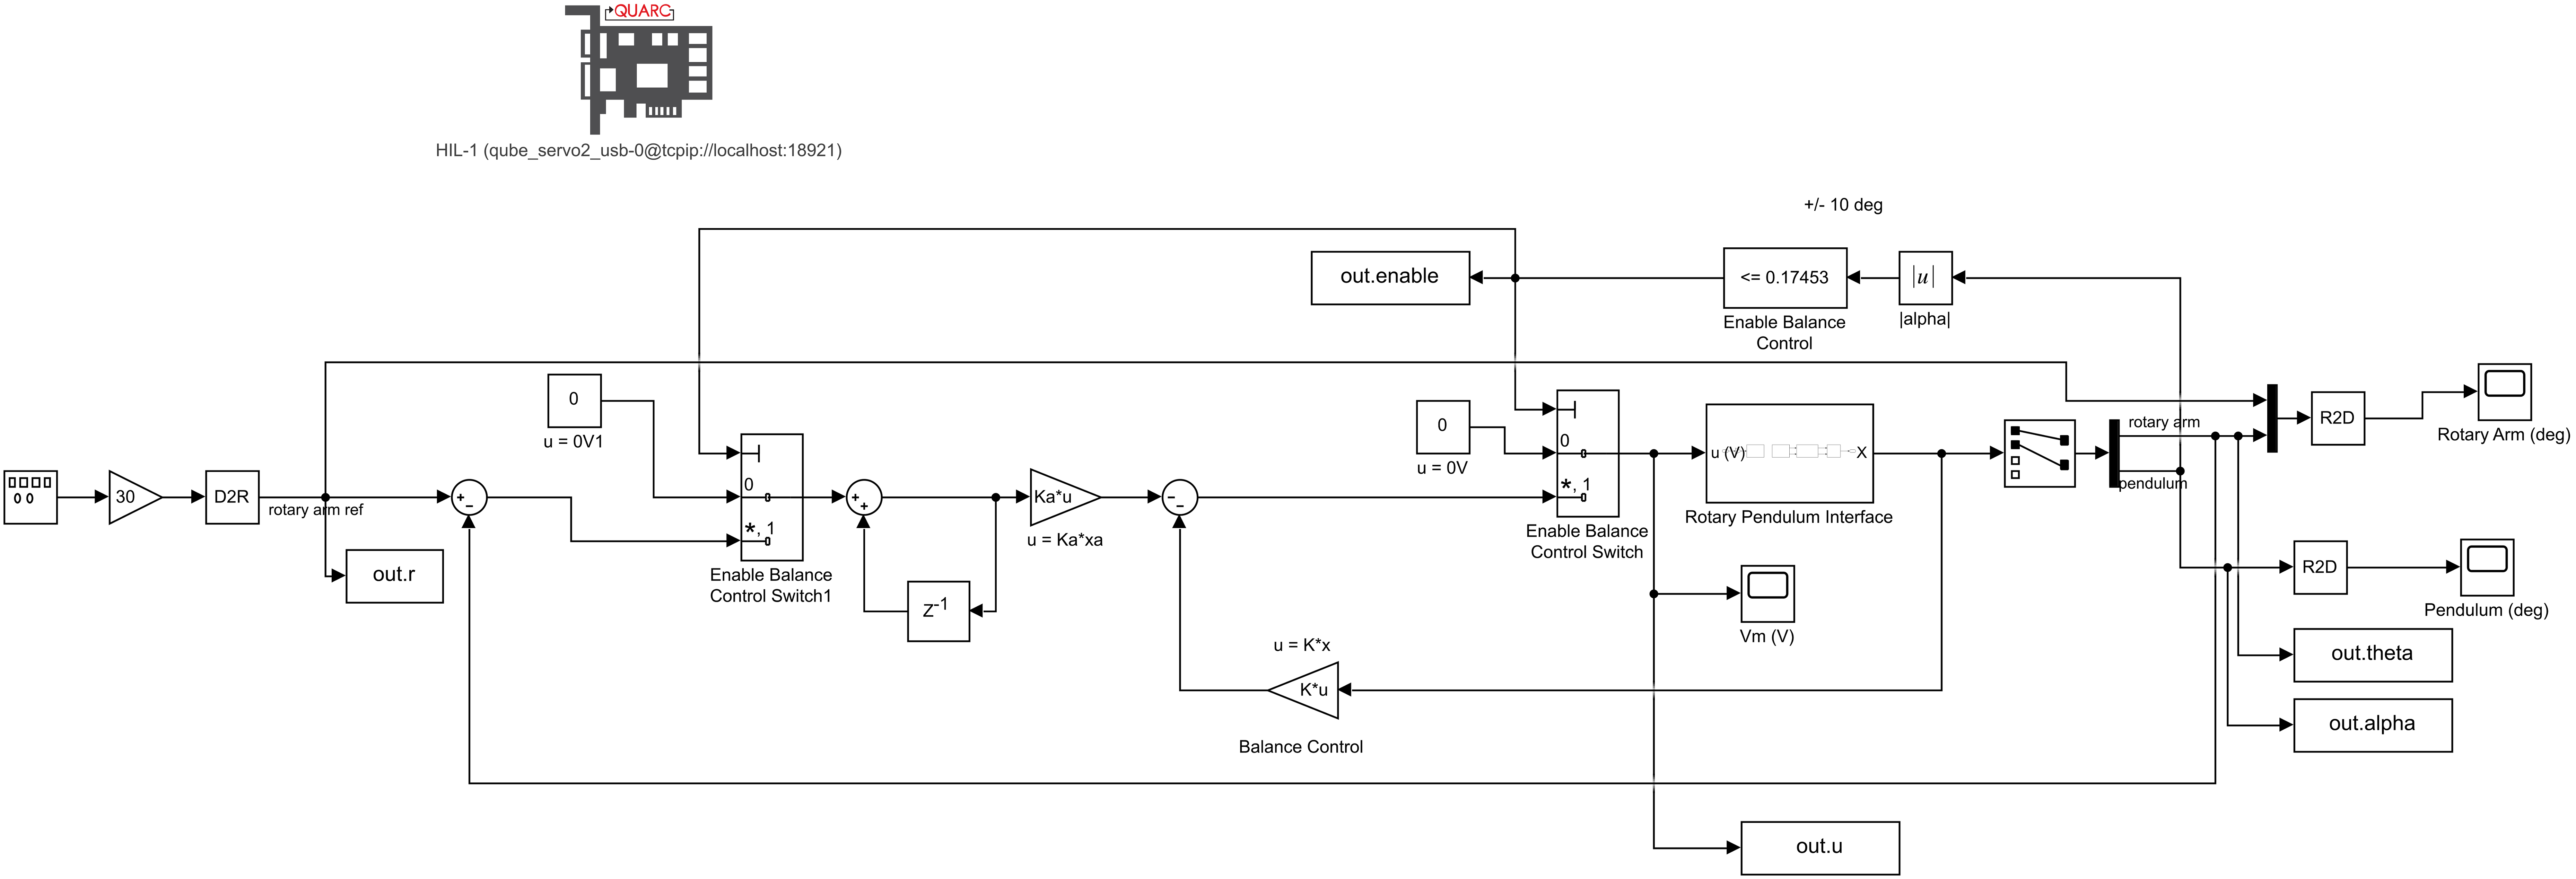

% Press lift pendulum while this is running (LED is green)
[t, u, r, theta, alpha] = run_serv();

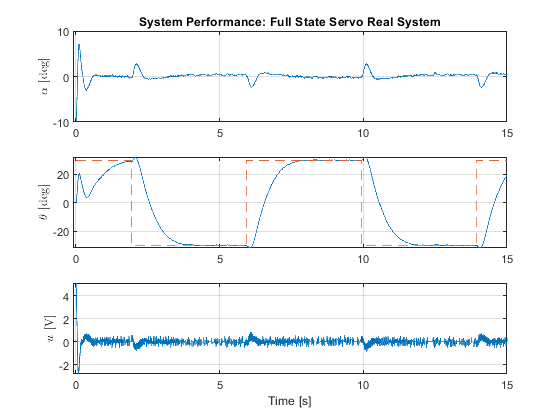

plot_performance(t, u, r, theta, alpha, 'Full State Servo Real System', 15);

### Servo LQR Weight Matrices

The performance is fine, let's print our poles:

Qaug

Qaug =          1000            0            0            0            0
            0            1            0            0            0
            0            0            1            0            0
            0            0            0            1            0
            0            0            0            0         0.03


R

R =    100

## LQG Controller Design (Kalman Filter)

### Verification With Simulation

Augmenting our system matrices for Kalman filtering:

n = size(sysd.A, 1); % # states
p = size(sysd.C, 1); % # outputs
tmpB = [sysd.B eye(n)];     % Augmented B-matrix
tmpD = [sysd.D zeros(p, n)]; % Augmented D-matrix
sysd_KF = ss(sysd.A, tmpB, sysd.C, tmpD, T);

Let's start with identity covariance matrices:

Qn = eye(n);
Rn = eye(p);
[~, L, ~] = kalman(sysd_KF,Qn,Rn);

Checking our observer performance with a Simulink simulation:

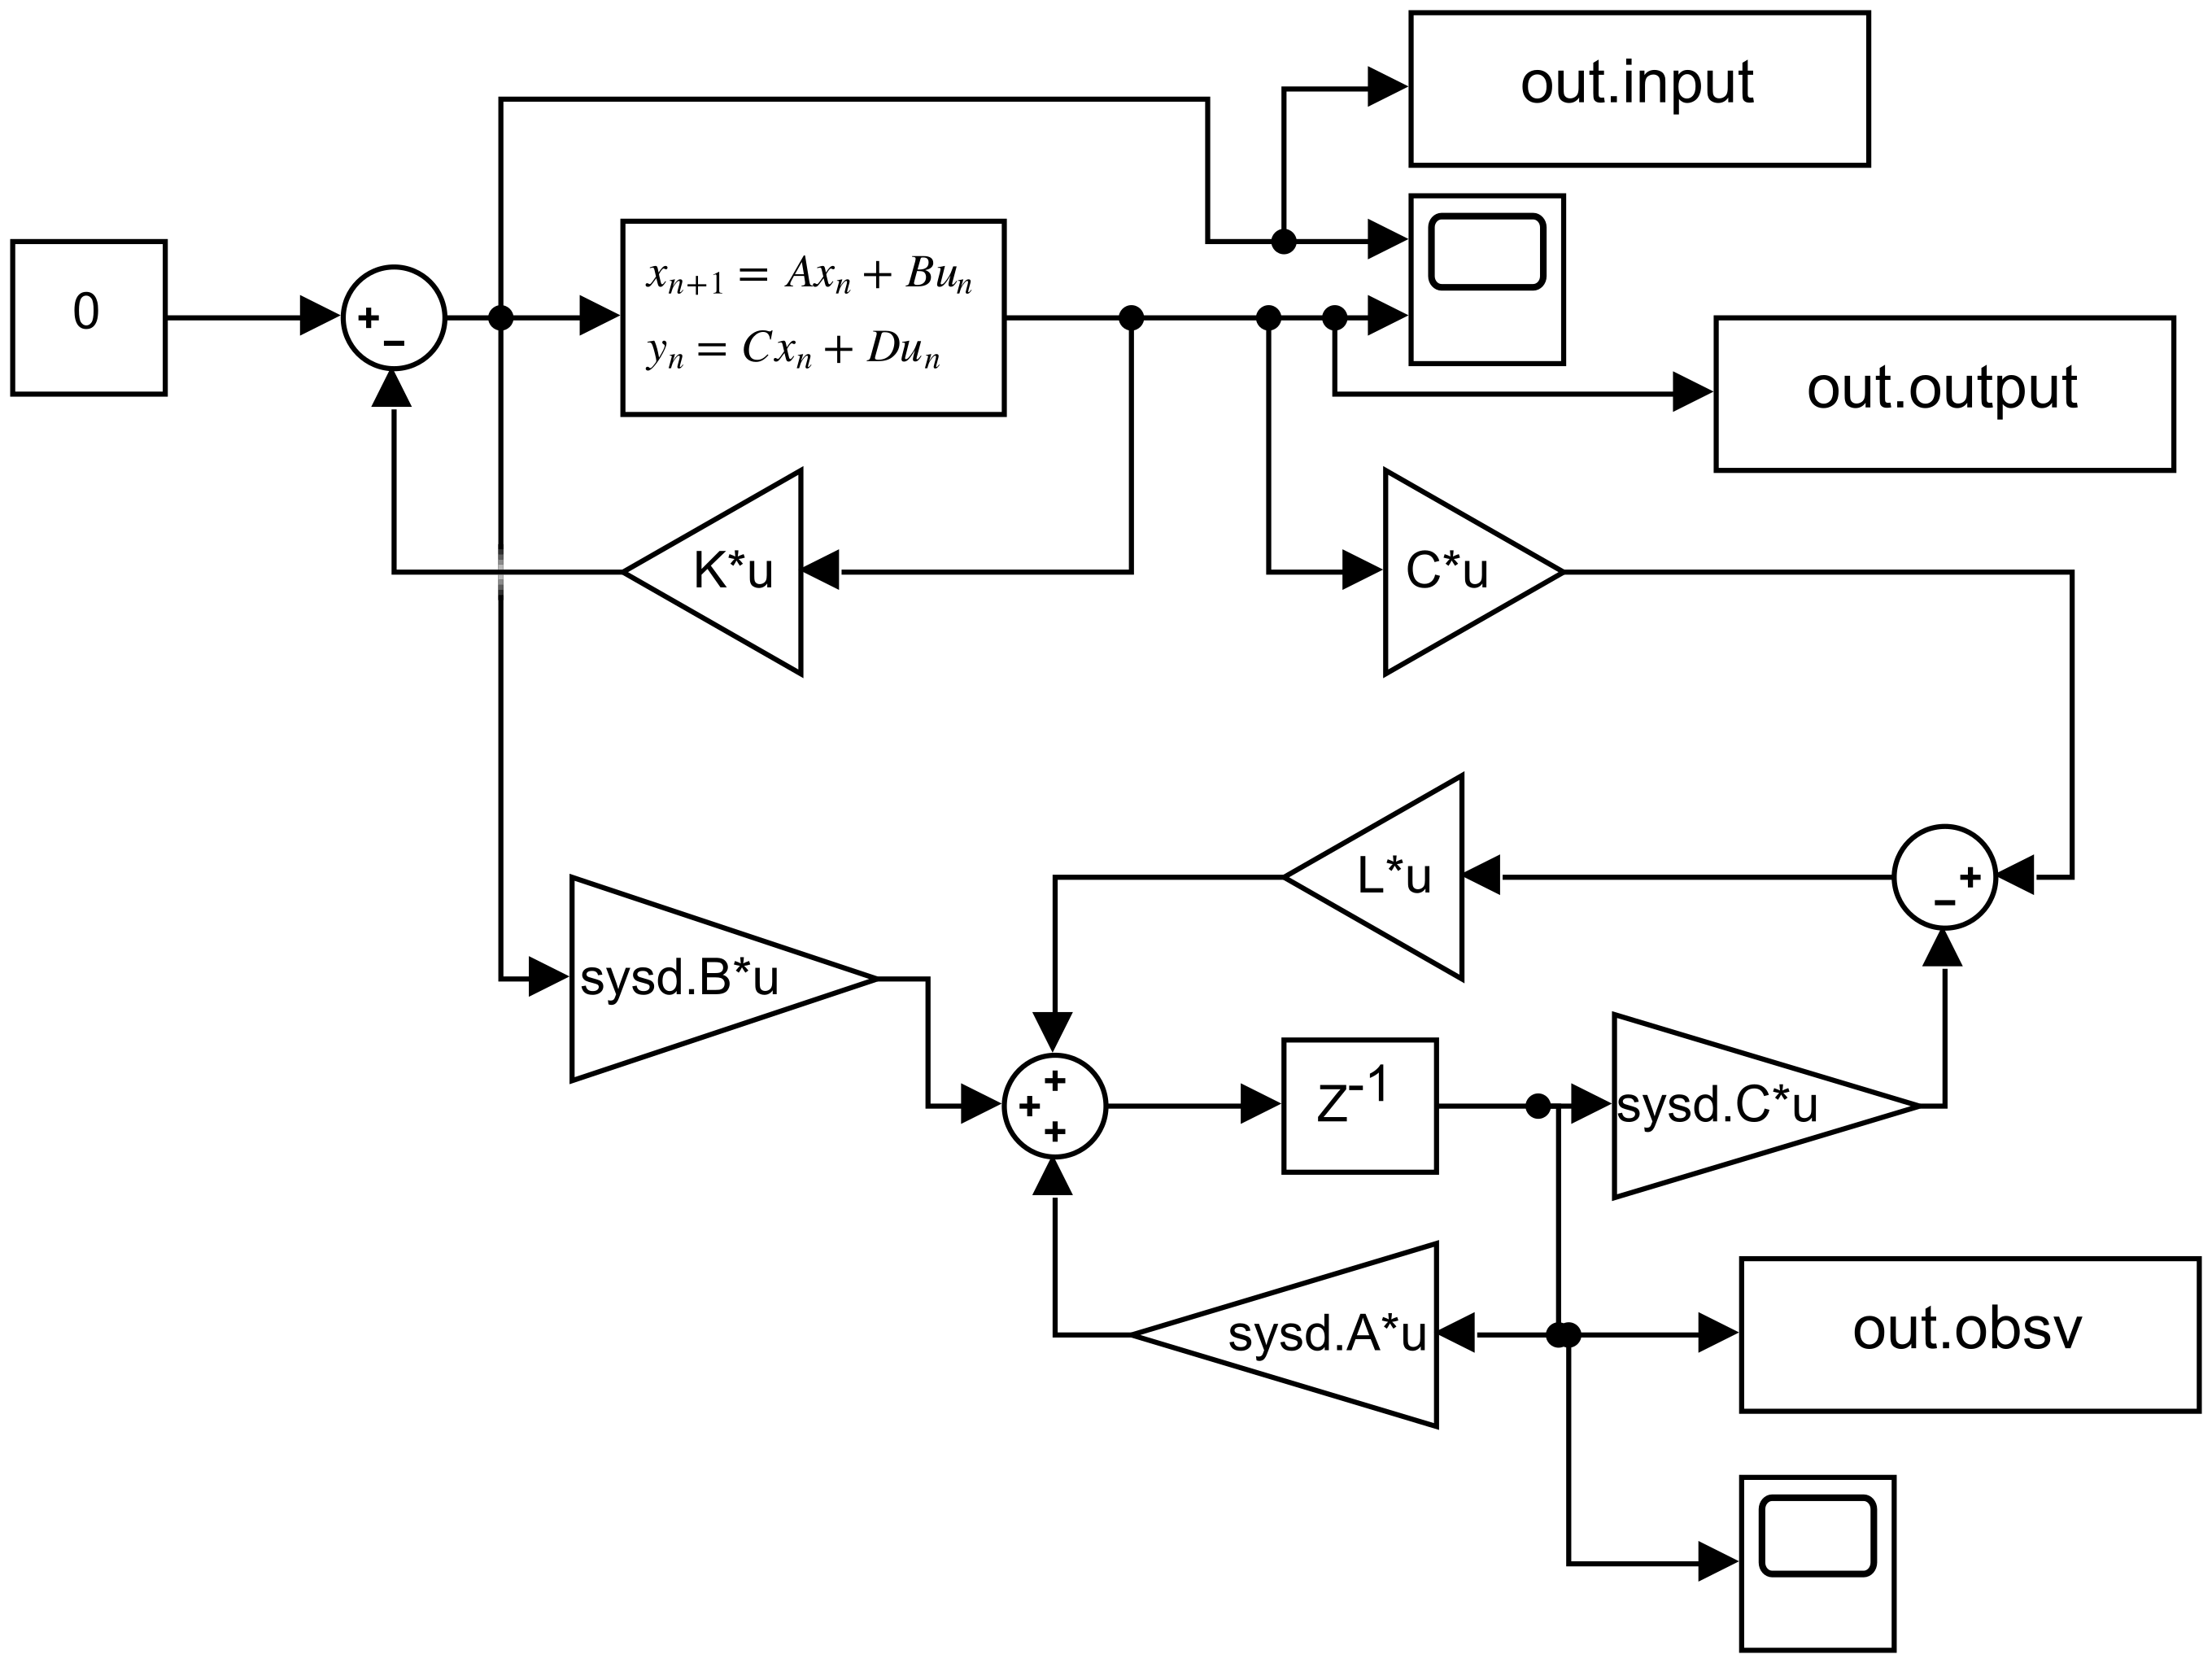

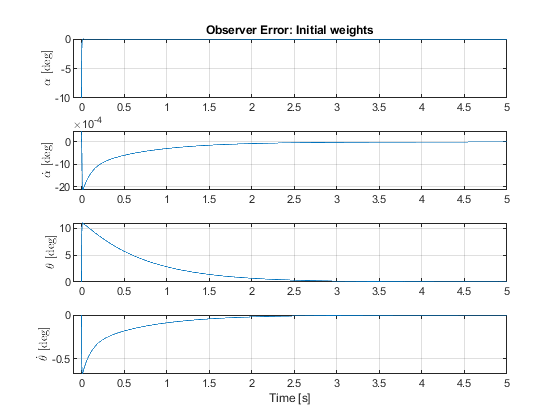

[t, ~, e_theta, e_alpha, e_dtheta, e_dalpha] = obsv_sim();
plot_observer(t, e_theta, e_alpha, e_dtheta, e_dalpha, 'Initial weights')

We see that the error in our already known states is pretty good, but the two derivatives have much poorer performance. If we increase the weights for those two states, we will improve the time it takes for the errors to converge, at the cost of a higher initial error, so we have to balance these two factors.

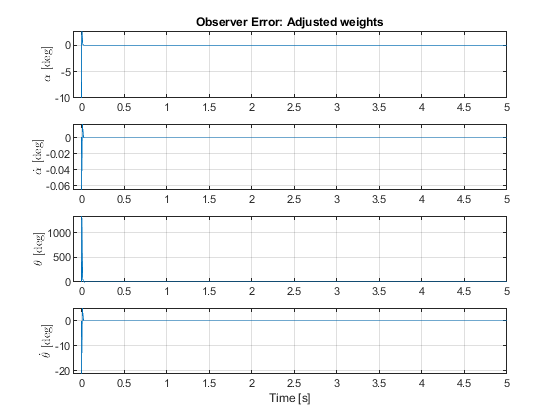

Qn(3,3) = 75000;
Qn(4, 4) = 75000;
[~, L, ~] = kalman(sysd_KF,Qn,Rn);
[t, ~, e_theta, e_alpha, e_dtheta, e_dalpha] = obsv_sim();
plot_observer(t, e_theta, e_alpha, e_dtheta, e_dalpha, 'Adjusted weights')

Now the observer performance is fairly good, but let's also simulate the entire observer based feedback system to ensure it is still actually stable.

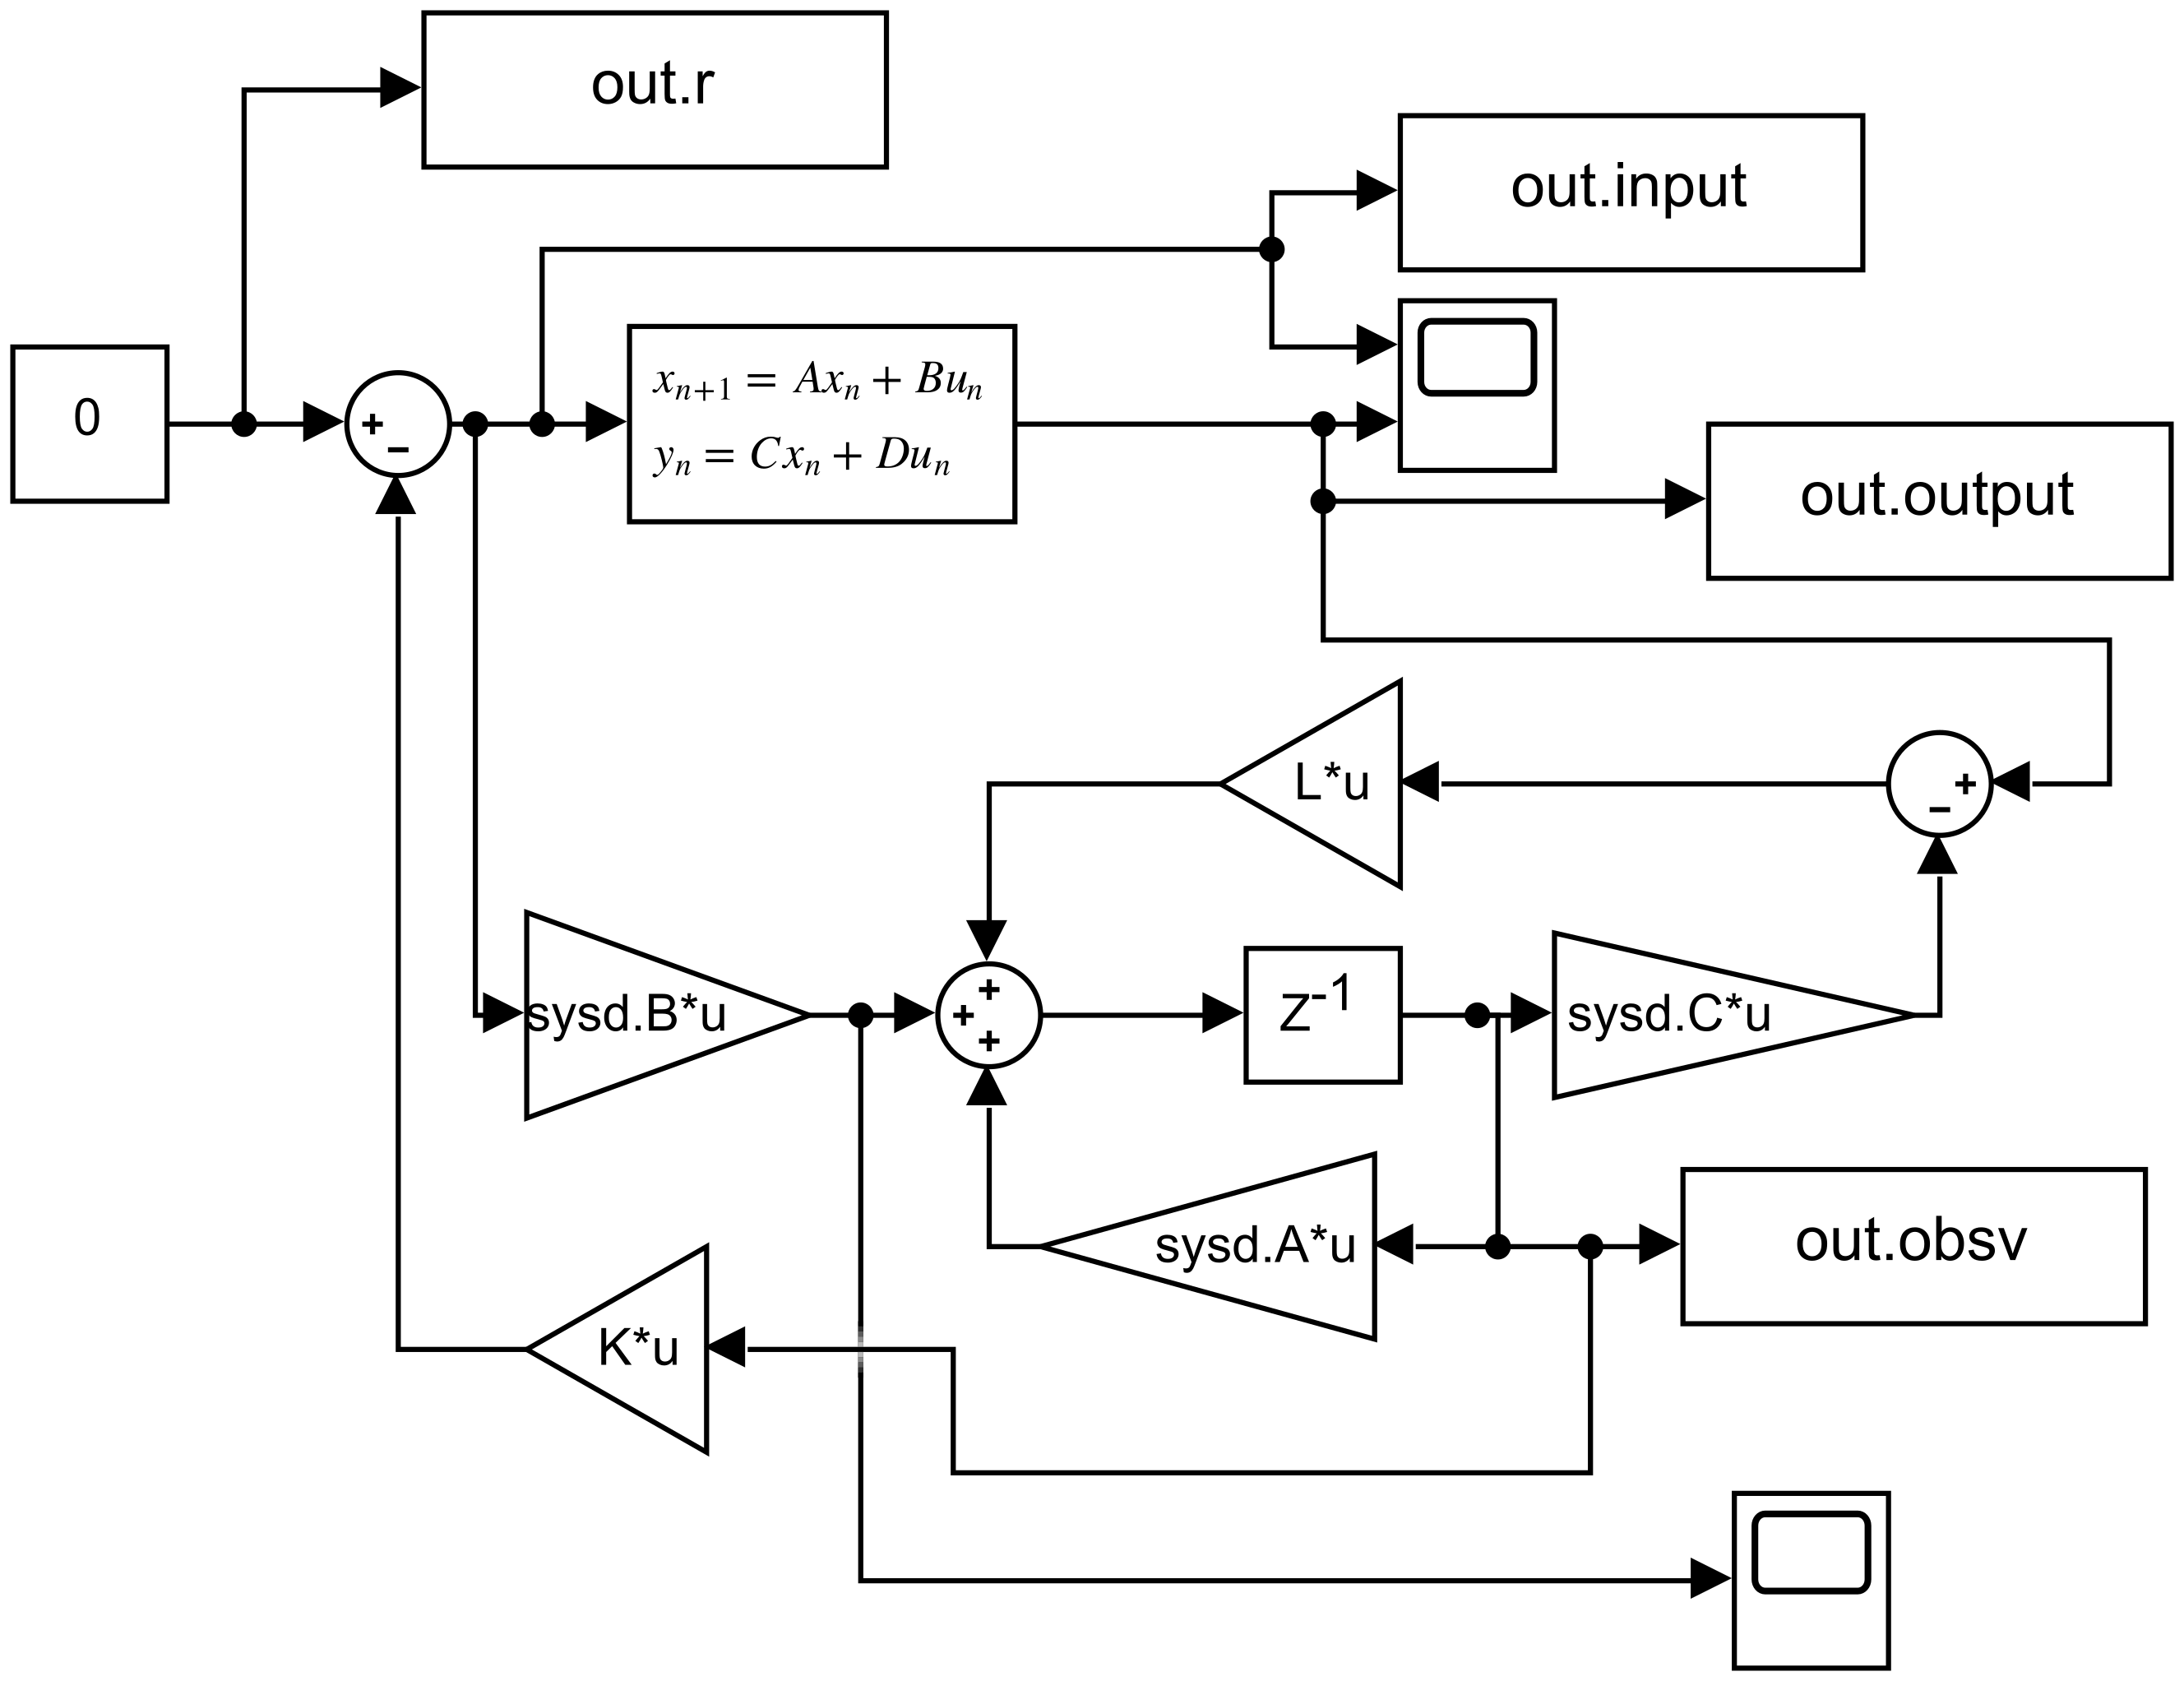

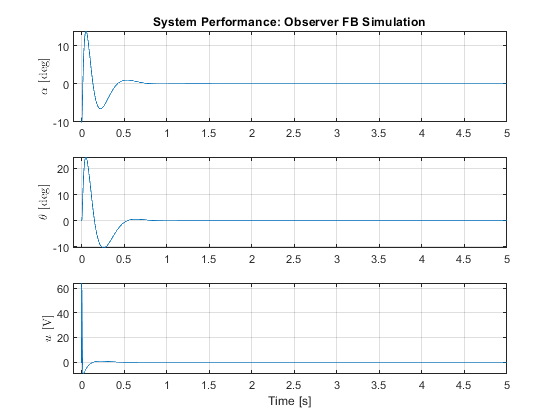

[t, u, r, theta, alpha] = obsv_fb_sim();
plot_performance(t, u, r, theta, alpha, 'Observer FB Simulation', 5);

### Testing with Real System

Testing it on the real system:

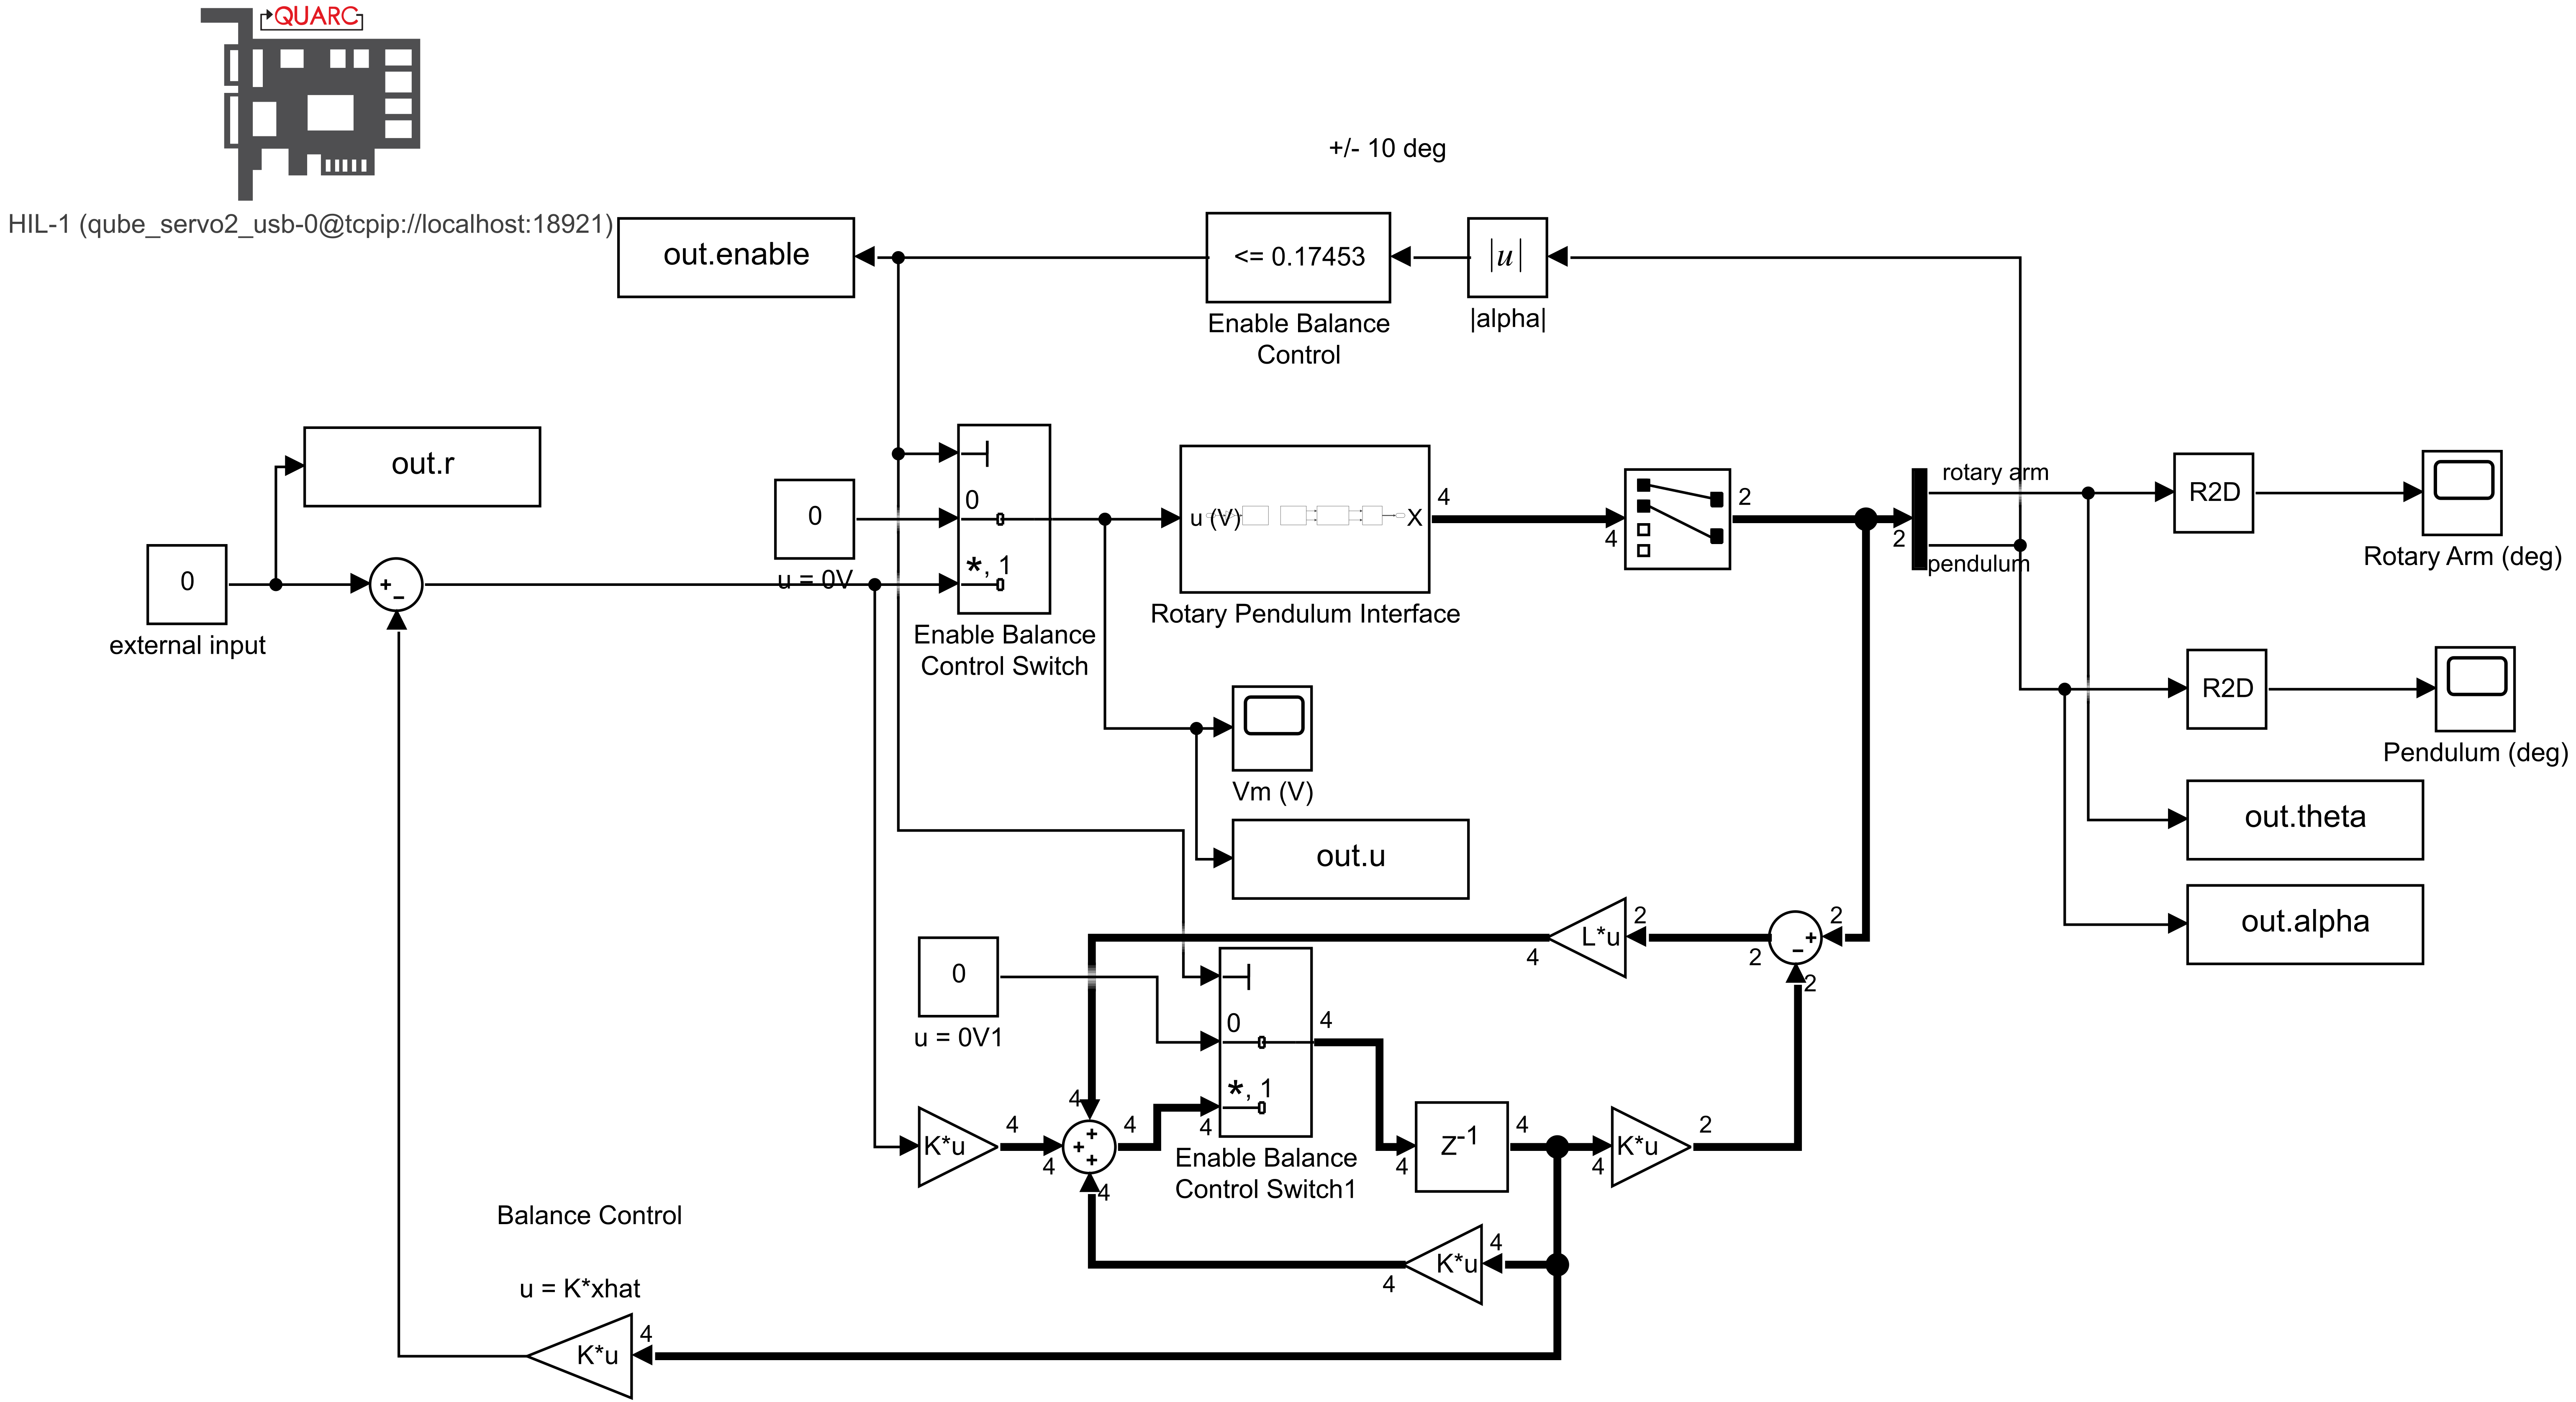

% Press lift pendulum while this is running (LED is green)
[t, u, r, theta, alpha] = run_obsv();

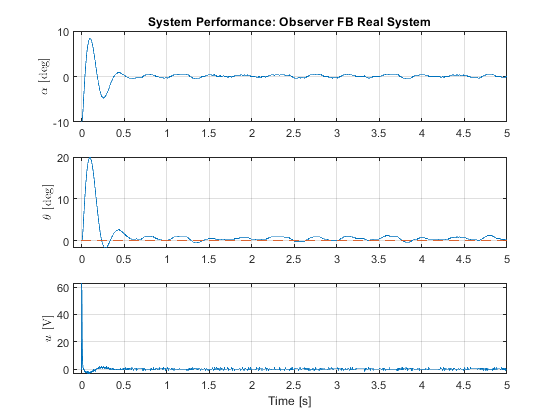

plot_performance(t, u, r, theta, alpha, 'Observer FB Real System', 5);

We can see that the system performance is still acceptable.

### Covariance Matrices

Let's print the Kalman filter covariance matrices:

Qn

Qn =            1           0           0           0
           0           1           0           0
           0           0       75000           0
           0           0           0       75000


Rn

Rn =      1     0
     0     1


## LQG Servo Controller

### Testing with Real System

Having already designed an observer and servo controller, we should just be able to use it directly with the real system:

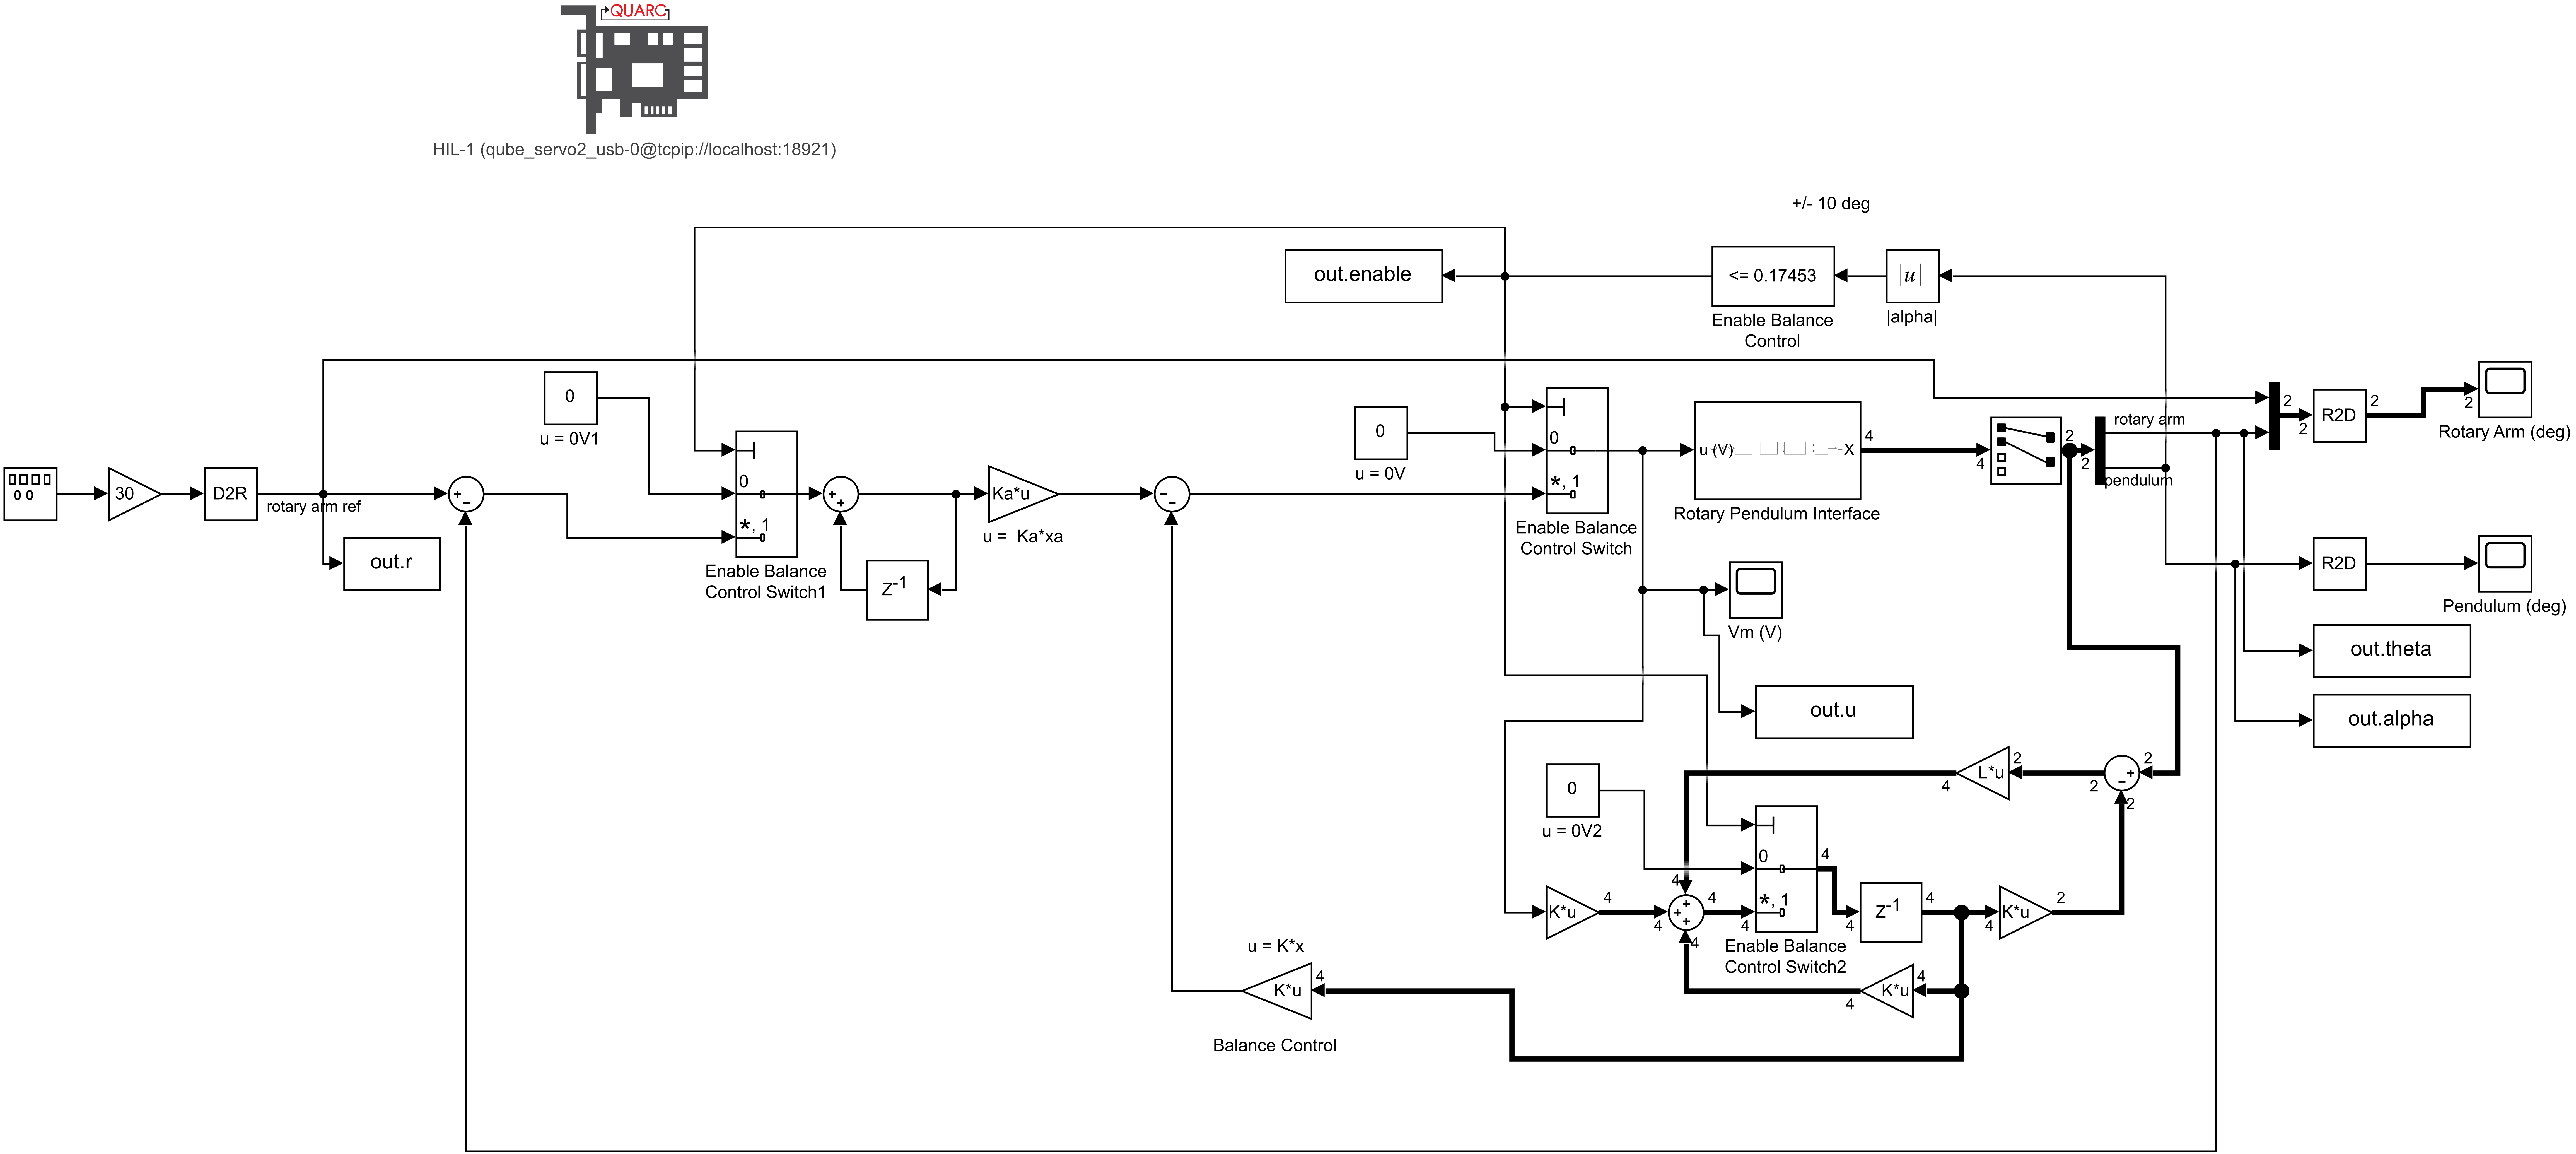

% Press lift pendulum while this is running (LED is green)
[t, u, r, theta, alpha] = run_obsv_serv();

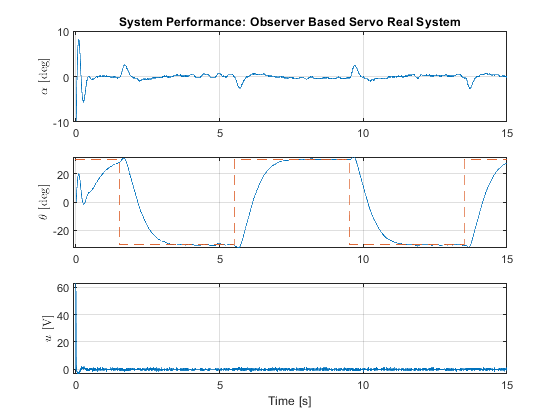

plot_performance(t, u, r, theta, alpha, 'Observer Based Servo Real System', 15);

## Appendix

### Force PNG output

Live script plot exports will randomly be a really low resolution bitmap instead of a vector image. In order to get decent figures we will force PNG output with a sufficiently high resolution.

s = settings;
s.matlab.editor.export.latex.FigureFormat.TemporaryValue = 'png';
s.matlab.editor.export.latex.FigureResolution.TemporaryValue = 1200;

### Simulink Model Export

Exporting all of our models as images:

simulink_files = dir('*.slx');
l = size(simulink_files, 1);
for i=1:l
    f_name = simulink_files(i).name;
    svg_name = strrep(f_name, '.slx', '.svg');
    open_system(f_name);
    print(svg_name, '-s', '-dsvg');
    % Use inkscape to get png images, built in printer is fairly low
    % quality
    system( ...
        sprintf('inkscape --export-type="png" --export-dpi=600 %s', svg_name));
end

### Functions

Live scripts require functions to be defined at the end of the file, so here are all of the definitions.

function plot_performance(t, u, r, theta, alpha, name, t_end)
vars = [rad2deg(alpha) rad2deg(theta) u];
labels = {'$\alpha$ [deg]', '$\theta$ [deg]', '$u$ [V]'};
fig = figure();
fig.Renderer = 'painters';
for i=1:3
    subplot(3, 1, i);
    plot(t, vars(:,i));
    if i==2
        hold on
        plot(t, rad2deg(r), '--');
    end
    hold off
    xlim([-0.1, t_end]);
    ylabel(labels(i), 'interpreter', 'latex');
    grid on
end
xlabel('Time [s]');
subplot(3, 1, 1);
title(sprintf('System Performance: %s', name))
end

function plot_observer(t, e_theta, e_alpha, e_dtheta, e_dalpha, name)
vars = [rad2deg(e_alpha) rad2deg(e_theta) rad2deg(e_dalpha) rad2deg(e_dtheta)];
labels = {
    '$\alpha$ [deg]', '$\theta$ [deg]', 
    '$\dot{\alpha}$ [deg]', '$\dot{\theta}$ [deg]'};
fig = figure();
fig.Renderer = 'painters';
for i=1:4
    subplot(4, 1, i);
    plot(t, vars(:,i));
    xlim([-0.1, 5]);
    ylabel(labels(i), 'interpreter', 'latex');
    grid on
end
xlabel('Time [s]');
subplot(4, 1, 1);
title(sprintf('Observer Error: %s', name));
end

function [t, u, r, theta, alpha] = fb_sim(model)
o = sim(model);
t = o.tout;
u = o.input.Data;
r = o.r.Data;
theta = o.output.Data(:, 1);
alpha = o.output.Data(:, 2);
end

function [t, u, r, theta, alpha] = fs_fb_sim()
[t, u, r, theta, alpha] = fb_sim("fullstate_sim");
end

function [t, u, r, theta, alpha] = fs_servo_sim()
[t, u, r, theta, alpha] = fb_sim("fullstate_servo_sim");
end

function [t, u, r, theta, alpha] = obsv_fb_sim()
[t, u, r, theta, alpha] = fb_sim("observer_fb_sim");
end

function [t, u, e_theta, e_alpha, e_dtheta, e_dalpha] = obsv_sim()
o = sim("observer_sim");
t = o.tout;
u = o.input.Data;
err = o.output.Data - o.obsv.Data;
e_theta = err(:, 1);
e_alpha = err(:, 2);
e_dtheta = err(:, 3);
e_dalpha = err(:, 4); 
end

function [t, u, r, theta, alpha] = run_qube(model, t_end)
o = sim(model, t_end);
t = o.tout;
enable = o.enable.Data;
t0_idx = find(enable, 1, 'first');
t0 = t(t0_idx);
t = t - t0;
t = t(t0_idx:end);
u = o.u.Data(t0_idx:end);
r = o.r.Data(t0_idx:end);
if size(r, 2) == 0
    r = 0*t;
end
theta = o.theta.Data(t0_idx:end);
alpha = o.alpha.Data(t0_idx:end);
end

function [t, u, r, theta, alpha] = run_sf()
[t, u, r, theta, alpha] = run_qube("HW5_LQR", 15);
end

function [t, u, r, theta, alpha] = run_obsv()
[t, u, r, theta, alpha] = run_qube("HW5_LQG", 15);
end

function [t, u, r, theta, alpha] = run_serv()
[t, u, r, theta, alpha] = run_qube("HW5_LQRServo", 25);
end

function [t, u, r, theta, alpha] = run_obsv_serv()
[t, u, r, theta, alpha] = run_qube("HW5_LQGServo", 25);
end